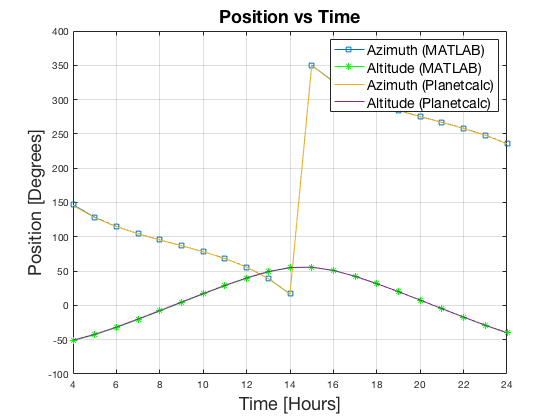

%Tracking Path Graph Generation
%------------------------------------------------------------------------------
%Author:      Cole Berry
%Institution: Stellenbosch University
%Student No.: 20934106
%------------------------------------------------------------------------------
%Description: This program file is identical to the scripts used in the 
%             "FinalScript" file and the GUI application with the exception that 
%             it does not contian the code that is used to control the motors over
%             the serial port. This program graphically illustrates the vectors 
%             that are generated for the repective axes of rotation.
%------------------------------------------------------------------------------
clear
clc
close all
%-----------------PositionOfSystem------------------
%--Latitude--
GMT=-2;
LAT_dir = 'south'; %north or south
LAT_pol =0;
if(LAT_dir == 'north')
    LAT_pol = 1;
elseif(LAT_dir == 'south')
    LAT_pol=-1;
else
    print('Incorrect Input')
end
LAT = Latitude(33,55,58,LAT_pol);%conversion to degrees

%--Longitude--
Long_dir = 'east'; %east or west
    Long_pol = 0;
    if(Long_dir == 'east')
        Long_pol = 1;
    elseif(Long_dir == 'west')
        Long_pol=-1;
    else
        print('Incorrect Input');
    end
LONG = Longitude(18,52,5,Long_pol); %conversion to degrees

%-----------------LocationOfCelestialObject------------------
%--Right Ascension Angle--
RA = RightAscension(12,0,32); %conversion to degrees
    
%--Declination Angle--
DEC = Declination(0,3,32); %FinalDeclinationAngle

%--set hours for the track--
Hour1=2;
Hour2=22;
 
%-----------------LocalSiderealTime1------------------
LST = LocalSiderealTime(2020,9,23,Hour1,0,GMT,LONG); %StartingLST

%--HourAngleCalculation--
HA = LST -RA; %in degrees

%-----------------LocalSiderealTime2------------------
LST2 = LocalSiderealTime(2020,9,23,Hour2,0,GMT,LONG);

%--set range for vectors--
if(Hour2==Hour1)
    range = (Hour2)+1;
else
    range = ((Hour2-Hour1))+1;
end

%--HourAngleOfEnding--
HA2 = LST2 -RA; %in degrees

%--CompensationForCrossing0or360--
p=0;
HA_diff = HA2-HA;
RA_HA=RA+HA_diff;
RA_shift= linspace(RA,RA_HA,range);
HA_past = linspace(HA,HA2,range);
for i=1:length(HA_past)
    if(HA_past(i)<0)
        p=p+1;
    end
end

%------------ConvertingHAandDECtoALTandAZ--------------------
[ALT2,Az2]=AltAz(HA_past,DEC,LAT); 

%---functional------
for i=1:(length(Az2)-p)
    Az2(p+i) = 360-Az2(p+i); %graphical path
    %Az2(p+i) = Az2(p+i)*-1; %real path for motors
end
%-----------------

%--PLANETCALC Calculated values--
%-----Online source data----
x = linspace (Hour1-GMT,Hour2-GMT,range);
AzPC = [145.93 ,127.92, 114.65, 104.25, 95.33, 86.91,78.19, 68.24, 55.79,39.01 ,16.29,349.68, 325.67, 307.61, 294.34, 283.95, 275.03, 266.62, 257.90,247.94, 235.48 ];
AltPC= [-50.72 ,-42.18, -31.53, -19.80, -7.55, 4.89, 17.22, 29.13, 40.12, 49.32, 55.15, 55.81, 51.03,42.44, 31.67, 20.01,7.74, -4.69, -17.01, -28.90,-39.87];
%----------

%--Plot the respective outputs--
plot(x,Az2,'-s')
grid on
hold on
plot(x,ALT2,'-*','Color','g')
hold on
plot(x,AzPC)
hold on
plot(x,AltPC)
alldatacursors = findall(gcf,'type','hggroup');
set(alldatacursors,'FontSize',18);
set(alldatacursors,'FontName','Times');
set(alldatacursors, 'FontWeight', 'bold');
title ('Position vs Time','FontSize',18);
legend ({'Azimuth (MATLAB)','Altitude (MATLAB)','Azimuth (Planetcalc)','Altitude (Planetcalc)'},'FontSize',14);
xlabel('Time [Hours]','FontSize',18);
ylabel('Position [Degrees]','FontSize',18);
grid on
length(x);
hold off

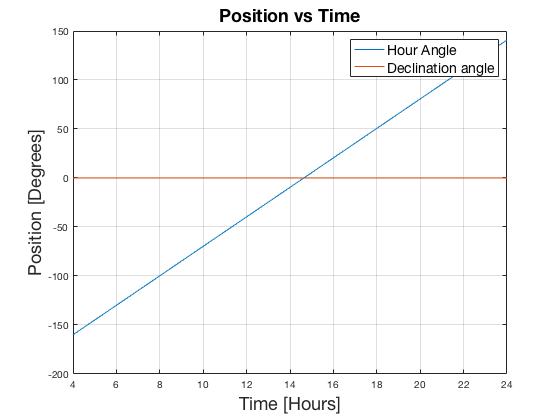


Dec_array = ones(1,range).*DEC;
LST_array = linspace(LST,LST2,range);

plot(x,HA_past)
hold on
plot(x,Dec_array)

grid on
legend ({'Hour Angle','Declination angle'},'FontSize',14)
title ('Position vs Time','FontSize',18)
xlabel('Time [Hours]','FontSize',18)
ylabel('Position [Degrees]','FontSize',18)
hold off